**Step 1: Read and Display an Image**

Read an image into the workspace, using the `imread` command. The example reads one of the sample images included with the toolbox, an image of a young girl in a file named `pout.tif` , and stores it in an array named `I` . `imread` infers from the file that the graphics file format is Tagged Image File Format (TIFF).

I = imread('pout.tif');

Display the image, using the `imshow` function. You can also view an image in the Image Viewer app. The `imtool` function opens the Image Viewer app which presents an integrated environment for displaying images and performing some common image processing tasks. The Image Viewer app provides all the image display capabilities of `imshow` but also provides access to several other tools for navigating and exploring images, such as scroll bars, the Pixel Region tool, Image Information tool, and the Contrast Adjustment tool.

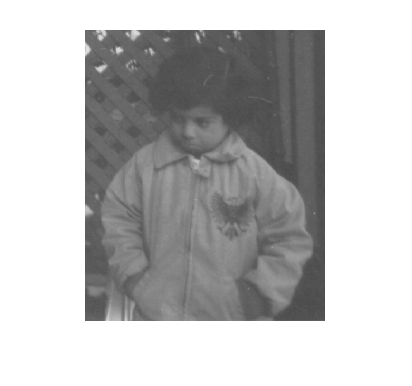

imshow(I)

**Step 2: Check How the Image Appears in the Workspace**

Check how the `imread` function stores the image data in the workspace, using the `whos` command. You can also check the variable in the Workspace Browser. The `imread` function returns the image data in the variable `I` , which is a 291-by-240 element array of `uint8` data.

whos I

  Name        Size             Bytes  Class    Attributes

  I         291x240            69840  uint8              



**Step 3: Improve Image Contrast**

View the distribution of image pixel intensities. The image `pout.tif` is a somewhat low contrast image. To see the distribution of intensities in the image, create a histogram by calling the `imhist` function. **(Precede the call to **`imhist`** with the figure command so that the histogram does not overwrite the display of the image **`I`** in the current figure window.)** Notice how the histogram indicates that the intensity range of the image is rather narrow. The range does not cover the potential range of [0, 255], and is missing the high and low values that would result in good contrast.

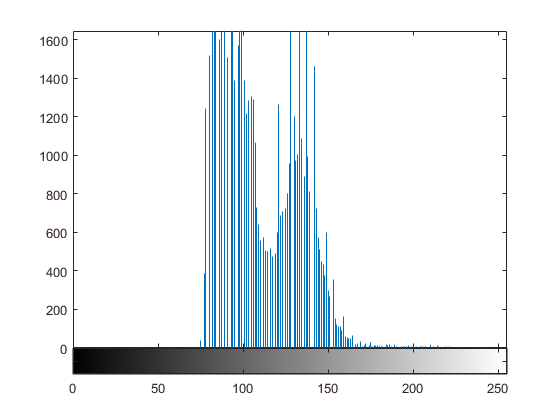

figure
imhist(I)

Improve the contrast in an image, using the `histeq` function. Histogram equalization spreads the intensity values over the full range of the image. Display the image. (The toolbox includes several other functions that perform contrast adjustment, including `imadjust` and `adapthisteq`, and interactive tools such as the Adjust Contrast tool, available in the Image Viewer.)

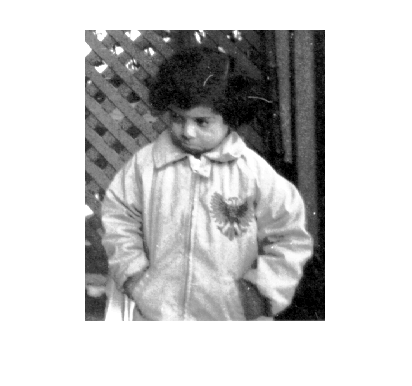

I2 = histeq(I);
figure
imshow(I2)

Call the `imhist` function again to create a histogram of the equalized image `I2` . If you compare the two histograms, you can see that the histogram of `I2` is more spread out over the entire range than the histogram of `I` .

figure

Error using figure
Invalid convenience arg handle


imhist(I2)

**Step 4: Write the Adjusted Image to a Disk File**

Write the newly adjusted image `I2` to a disk file, using the `imwrite` function. This example includes the filename extension `'.png'`  in the file name, so the `imwrite` function writes the image to a file in Portable Network Graphics (PNG) format, but you can specify other formats.

imwrite (I2, 'pout2.png');

**Step 5: Check the Contents of the Newly Written File**

View what `imwrite` wrote to the disk file, using the `imfinfo` function. The `imfinfo` function returns information about the image in the file, such as its format, size, width, and height.

imfinfo('pout2.png')